% NSCI0011
% Analysis  - unweighted

d = tracedroiconnections; 

% Create digraphs for each brain region (region for short)
% and store them in a cell array for further analysis

% how many brain regions? 
[gc, gr] = groupcounts(d{:, 3}); 

% create unweighted digraph for each brain region
GStore0 = {}; 
wmin = 0; % min weight to be included in graph
for k = 1:length(gr)
    idx = (d{:, 3} == gr(k))&(d{:, 4} > wmin); 
    bodyPre = d{idx, 1}; 
    bodyPost = d{idx, 2}; 

    tempG = simplify(digraph(cellstr(bodyPre), cellstr(bodyPost))); 
    GStore0{k} = tempG; 
end

% assess all basal properties of digraphs
nNL = zeros(length(gr), 1); 
nEL = zeros(length(gr), 1); 
for k = 1:length(gr)
    nNL(k) = GStore0{k}.numnodes; 
    nEL(k) = GStore0{k}.numedges; 
end

% calculate average_path_length and clustering_coefficient
% under unweighted condition
aplL = zeros(length(gr), 1); 
gccL = zeros(length(gr), 1); 
for k = 1:length(gr)
    aplL(k) = average_path_length(GStore0{k}); 
    gccL(k) = global_cc(GStore0{k}); 
end

% construct a list of corresponding E-Renyi random graph
ERRGList = {}; 
for k = 1:length(gr)
    ERRGList{k} = makerandCIJ_dir(GStore0{k}.numnodes, GStore0{k}.numedges); 
end

PRG3List = {}; % random graphs which preserve the node degree distribution, rewired 3 times; 
for k = 1:length(gr)
    PRG3List{k} = randmio_dir(adjacency(GStore0{k}), 3); 
end

PLG3List = {}; % lattice graphs which preserve the node degree distribution, rewired 3 times; 
for k = 1:30
    PLG3List{k} = latmio_dir(adjacency(GStore0{k}), 3); 
    disp('one iteration!')
end

aplERRGL = zeros(length(gr), 1); 
gccERRGL = zeros(length(gr), 1); 
for k = 1:length(gr)
    aplERRGL(k) = average_path_length(digraph(ERRGList{k})); 
    gccERRGL(k) = global_cc(digraph(ERRGList{k})); 
end

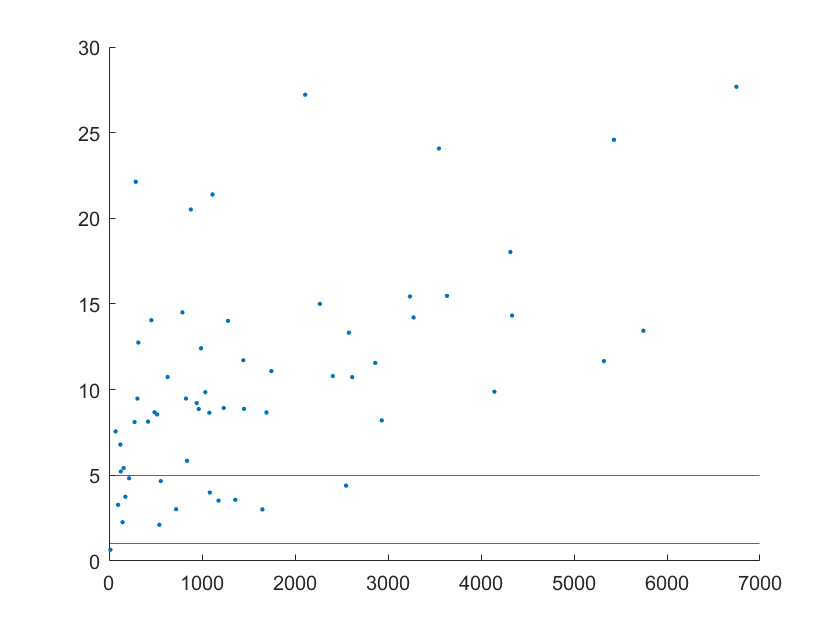


% calculate Humphrey's coeff with ERRGList
hcoeffL = zeros(61:1); 
for k = 1:61
    hcoeffL(k) = (gccL(k)/gccERRGL(k))/(aplL(k)/aplERRGL(k)); 
end


% calculate cpl (a substitute of apl) and gcc of the networks.. 
cplL = zeros(61, 1); 
for k =1:61
    cplL(k) = characteristic_path_length(GStore0{k}); 
end

cplPRG3L = zeros(61, 1); 
for k =1:61
    cplPRG3L(k) = characteristic_path_length(digraph(PRG3List{k})); 
end

gccPLG3L = zeros(61, 1); 
for k = 1:61
    gccPLG3L(k) = global_cc(digraph(PLG3List{k})); 
end

gccPRG3L = zeros(61, 1); 
for k =1:61
    gccPRG3L(k) = global_cc(digraph(PRG3List{k})); 
end

cplPLG3L = zeros(61, 1); 
for k = 1:61
    cplPLG3L(k) = characteristic_path_length(digraph(PLG3List{k})); 
end

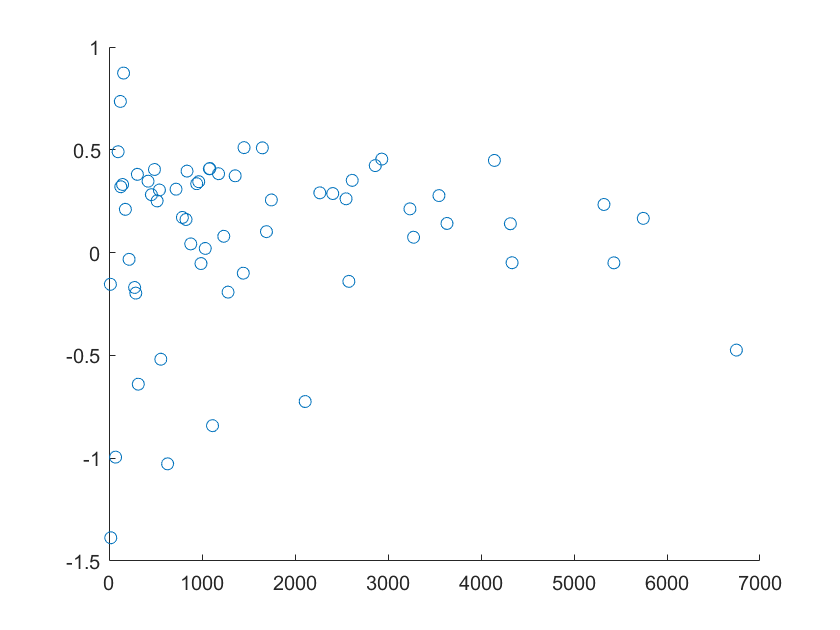

% t's coeff

tcoeffL = zeros(61, 1); 
for k = 1:61
    tcoeffL(k) = (cplPRG3L(k)/cplL(k))-(gccL(k)/gccPLG3L(k)); 
end

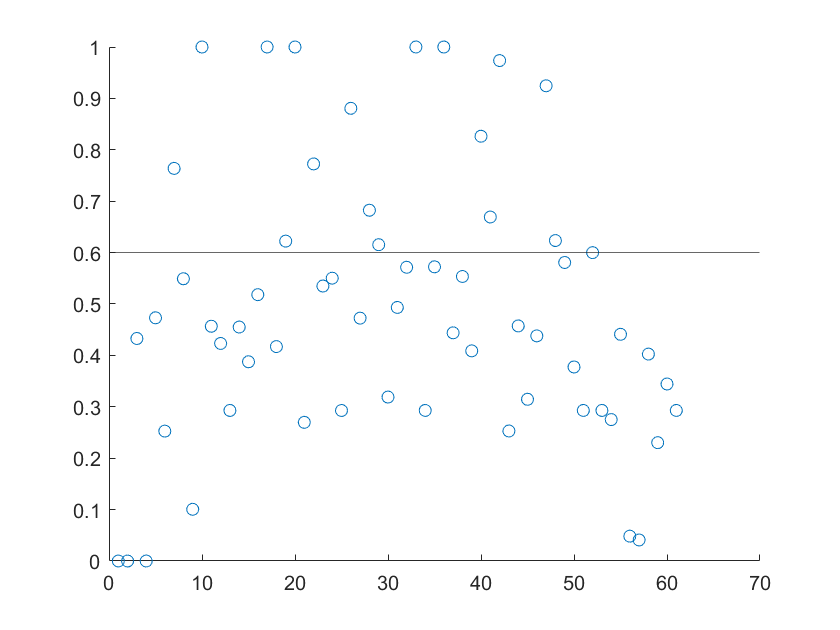

Dot indexing is not supported for variables of this type.

Error in h_significance_level (line 3)
n = G.numnodes; 

% small world propensity
swpL = zeros(61, 1); 
for k = 1:61
    swpL = small_world_propensity(adjacency(GStore0{k}), 'bin');
end